# Interactively Read Data from NetCDF File

This example shows how to use the **Import Data** task to explore the structure of a netCDF file, import data from the file, and then analyze and visualize the data.

## Download Dataset

The US National Oceanic and Atmospheric Administration Physical Sciences Laboratory (NOAA PSL) hosts a dataset of interpolated snow cover data for the Northern Hemisphere that was compiled by the National Snow and Ice Data Center (NSIDC). Download this dataset to your current folder.

filename = "snowcover.mon.mean.nc";
url = "https://downloads.psl.noaa.gov/Datasets/snowcover/snowcover.mon.mean.nc";
fullLocalPath = websave(filename,url);

## Explore and Import Data

Open the **Import Data** task in the Live Editor by selecting **Task > Import Data** on the **Live Editor** tab. Enter the filename of the netCDF dataset, `snowcover.mon.mean.nc`, in the **File** field. Use the task to explore the structure of the data, including the variables and their attributes:

- The global attributes give a general sense of the data contained in the file, including references.

- The dataset contains three dimensions: two spatial (`lat` and `lon`) and one temporal (`time`).

- The `lat` variable has a size of 90 and an attribute named `units`, which has value `'degrees_north'`. This variable represents the latitude, measured in degrees north of the equator, of a point at which a measurement is made.

- The `lon` variable has a size of 360 and an attribute named `units`, which has value `'degrees_east'`. This variable represents the longitude, measured in degrees east of the prime meridian, of a point at which a measurement is made.

- The `time` variable has a size of 297 with an unlimited dimension and an attribute named `units`, which has value `'hours since 1800-01-01 00:00:0.0'`. This variable represents the time at which a measurement is made.

- The `snowcover` variable has a size of 360-by-90-by-297 with the third dimension unlimited, an attribute named `units`, which has value `'%'`, and an attribute named `long_name`, which has value `'Monthly Means Snowcover Extent'`. The `snowcover` variable unites the `lat`, `lon`, and `time` variables. It represents the monthly mean of snow cover at a particular point in the Northern Hemisphere, at a particular month, measured in percentage of ground covered by snow.

Select and import the data from the `lat`, `lon`, `time`, and `snowcover` variables.

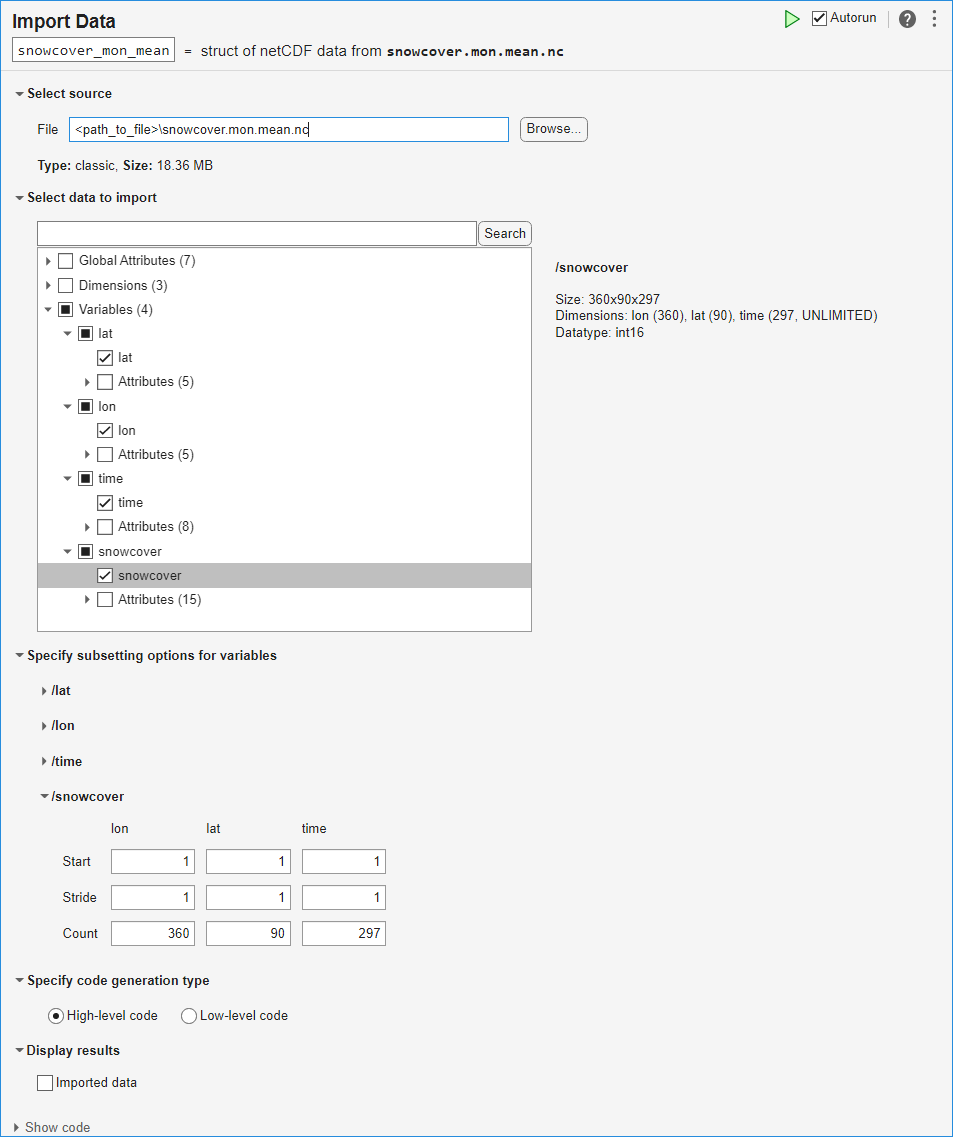

To see the code that this task generates, expand the task display by clicking **Show code** at the bottom of the task parameter area.

% Create a structure to store imported netCDF data
snowcover_mon_mean = struct();

filename = "snowcover.mon.mean.nc";
snowcover_mon_mean.Variables(1).Name = "lat";
snowcover_mon_mean.Variables(2).Name = "lon";
snowcover_mon_mean.Variables(3).Name = "time";
snowcover_mon_mean.Variables(4).Name = "snowcover";

snowcover_mon_mean.Variables(1).Value = ncread(filename, "/lat");

snowcover_mon_mean.Variables(2).Value = ncread(filename, "/lon");

snowcover_mon_mean.Variables(3).Value = ncread(filename, "/time");

snowcover_mon_mean.Variables(4).Value = ncread(filename, "/snowcover");

clear filename

## Organize and Prepare Data

Make local variables for each of the variables from the dataset.

lats = snowcover_mon_mean.Variables(1).Value;
lons = snowcover_mon_mean.Variables(2).Value;
times = snowcover_mon_mean.Variables(3).Value;
snows = snowcover_mon_mean.Variables(4).Value;

Make display versions of `lats` and `lons` to prepare for plotting the data. Choose a display scale that shows ten labels on each axis.

numLabels = 10;

latDisps = strings(length(lats),1);
latsLabelInterval = length(lats)/numLabels;
latLabelInds = latsLabelInterval:latsLabelInterval:length(lats);
latDisps(latLabelInds) = lats(latLabelInds);

lonDisps = strings(length(lons),1);
lonsLabelInterval = length(lons)/numLabels;
lonLabelInds = lonsLabelInterval:lonsLabelInterval:length(lons);
lonDisps(lonLabelInds) = lons(lonLabelInds);

The `units` attribute of the `time` variable indicates that `time` is measured in hours since the beginning of the year 1800. Further, the `long_name` attribute of the `snowcover` variable indicates that the values are monthly means. Use this information to convert the `times` vector into corresponding `datetime` values and also to make a display version of `times` that includes the month and year but suppresses the day.

sampTimes = datetime("1800-01-01 00:00:00") + hours(times);
sampTimes.Format = "MMM-yyyy";
sampTimeDisps = string(sampTimes);

The first dimension of `snows` represents a latitude and the second a longitude. To make a heatmap of this data, the first dimension should correspond to a column (longitude) and the second to a row (latitude). Permute these two dimensions of `snows`.

snows = permute(snows,[2 1 3]);

## Plot Data

Create a heatmap for the first month of data.

h = heatmap(lons,lats,snows(:,:,1));
h.XLabel = "Longitude (°E)";
h.YLabel = "Latitude (°N)";
h.XDisplayLabels = lonDisps;
h.YDisplayLabels = latDisps;
h.Colormap = winter;
h.GridVisible = "off";

Animate the heatmap by looping through the data for all available times.

for i = 1:numel(sampTimeDisps)
    h.ColorData = snows(:,:,i);
    h.Title = "Percent Snow Cover vs. Location (" + sampTimeDisps(i) + ")";
    pause(0.1)
end

## Find Time of Maximum Snow Cover

Compute and plot the total snow cover as a function of time.

cumSnowsbyTime = squeeze(sum(snows,[1 2])) / (length(lats)*length(lons));

plot(sampTimes,cumSnowsbyTime)
xlabel("Date")
ylabel("Total Snow Cover (%)")
title("Total Snow Cover vs. Date")

Find and plot the time of maximum snow cover.

[maxSnowsbyTime,maxSnowsbyTimeInd] = max(cumSnowsbyTime);

h = heatmap(lons,lats,snows(:,:,maxSnowsbyTimeInd));
h.XLabel = "Longitude (°E)";
h.YLabel = "Latitude (°N)";
h.Title = "Percent Snow Cover vs. Location (" + sampTimeDisps(maxSnowsbyTimeInd) + ")";
h.XDisplayLabels = lonDisps;
h.YDisplayLabels = latDisps;
h.Colormap = winter;
h.GridVisible = "off";

The month of maximal snow cover was February 1978.

## Find Locations of Maximum Snow Cover

Compute and plot the average snow cover as a function of location.

cumSnowsbyLoc = sum(snows,3) / length(times);

h = heatmap(lons,lats,cumSnowsbyLoc);
h.XLabel = "Longitude (°E)";
h.YLabel = "Latitude (°N)";
h.Title = "Average Percent Snow Cover vs. Location";
h.XDisplayLabels = lonDisps;
h.YDisplayLabels = latDisps;
h.Colormap = winter;
h.GridVisible = "off";

Find and plot the locations of maximum snow cover.

maxSnowsbyLocVal = max(cumSnowsbyLoc,[],"all");
maxSnowsbyLoc = maxSnowsbyLocVal*(cumSnowsbyLoc == maxSnowsbyLocVal);

h = heatmap(lons,lats,maxSnowsbyLoc);
h.XLabel = "Longitude (°E)";
h.YLabel = "Latitude (°N)";
h.Title = "Locations of Maximum Snow Cover";
h.XDisplayLabels = lonDisps;
h.YDisplayLabels = latDisps;
h.Colormap = winter;
h.GridVisible = "off";

The locations of maximum snow cover include most of Greenland, and parts of Svalbard and Franz Josef Land.

## Credits

NH Ease-Grid Snow Cover data provided by the NOAA PSL, Boulder, Colorado, USA, from their website at [`https://psl.noaa.gov`](https://psl.noaa.gov/).

*Copyright 2023 The MathWorks, Inc.*